### **Matrix decompositions**

**Exploring Matrix Decomposition Techniques with Simulated Train Schedule Data**

Matrix decomposition is a cornerstone of computational mathematics, providing powerful tools for analyzing and transforming data. In this project, I explored multiple matrix decomposition techniques—Schur, Cholesky, QR, LU, and Singular Value Decomposition (SVD)—on a simulated dataset of train schedules. Each decomposition served a unique purpose, helping me uncover the structure, patterns, and properties of the data while offering valuable insights into its mathematical representation.

**Simulating Train Schedule Data**

I began by generating a large dataset to simulate train schedules, with each row representing a station and each column corresponding to a specific time interval. The entries in the matrix were randomly generated to reflect the variability of train arrivals and departures. With 1,000 stations and 1,000 time intervals, the dataset was sufficiently large to test the efficacy of various decomposition techniques.

To simulate real-world challenges, I ensured the dataset's suitability for different decompositions. For example, I constructed a positive definite matrix for Cholesky decomposition by multiplying the train data with its transpose.**Schur Decomposition**

The Schur decomposition allowed me to break the dataset into a unitary matrix (Q) and an upper triangular matrix (T). This technique provided insights into the eigenvalues and hierarchical structure of the train data. It served as a foundation for analyzing the stability and interactions between rows and columns. Validating the reconstruction of the matrix from its decomposed components reassured me of the method’s accuracy and suitability.

**Cholesky Decomposition**

Cholesky decomposition requires a positive definite matrix, which I created by multiplying the original train data with its transpose. This decomposition yielded an upper triangular matrix (R) and its transpose (L). By reconstructing the original matrix from these components, I verified the decomposition’s precision. This technique is particularly useful for applications involving covariance matrices, such as assessing the relationship between train stations and scheduling patterns.

**QR Decomposition**

With QR decomposition, I represented the train data as a product of an orthogonal matrix (Q) and an upper triangular matrix (R). This decomposition helped me identify orthogonal patterns in the dataset, which can be crucial for minimizing redundancy and understanding the linear independence of schedules across stations. Reconstructing the original matrix from Q and R demonstrated the reliability of this approach.

**LU Decomposition**

LU decomposition decomposes a matrix into lower (L) and upper (U) triangular matrices, with an optional permutation matrix (P) to enhance numerical stability. By applying this method, I gained insights into the row and column interactions within the dataset, making it easier to analyze the flow of schedules across stations. Validating the decomposition by reconstructing the matrix confirmed its robustness.

**Singular Value Decomposition (SVD)**

SVD was the most insightful decomposition technique, as it revealed the underlying structure of the train data. By breaking the matrix into left singular vectors (U), singular values (S), and right singular vectors (V), I could identify dominant patterns and reduce the dimensionality of the dataset without significant loss of information. Visualizing the singular values highlighted the relative importance of different components, offering a clear picture of how schedules varied across stations and times.

**Validation and Visualization**

Ensuring the accuracy of each decomposition was a critical step. I validated every technique by reconstructing the original matrix from its decomposed components and measuring the reconstruction error using the Frobenius norm. Each decomposition passed the validation tests, confirming the reliability of the methods applied.

To further understand the dataset’s structure, I visualized the singular values obtained from SVD. The plot revealed the contribution of each singular value, emphasizing the dataset’s inherent rank and variability.**Reflections and Applications**

This exploration reinforced the importance of matrix decomposition in data analysis. Each technique offered unique advantages, from understanding eigenvalues with Schur decomposition to uncovering dominant patterns with SVD. The ability to validate these decompositions ensured the integrity of the results, and the insights gained could be extended to practical applications such as optimizing train schedules or modeling network flows.

Matrix decomposition is not just a mathematical exercise; it is a gateway to understanding complex datasets. By applying these techniques to simulated train schedule data, I gained a deeper appreciation for their versatility and power in solving real-world problems. This project showcased how decomposition methods can simplify intricate systems and provide actionable insights for decision-making and optimization.

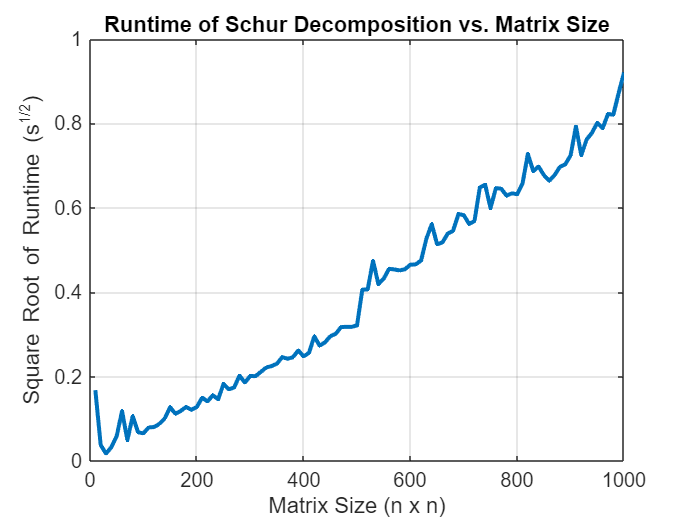

% Chapter 11: Matrix Decompositions
% Section 11.1: Schur Decomposition with Runtime Analysis

% Step 1: Define a complex, quadratic matrix
A = [3, 6, 1; 
     23, 13, 1; 
     0, 3, 4];

% Step 2: Initialize runtime measurement variables
matrix_sizes = 10:10:1000; % Range of matrix sizes
runtimes = zeros(size(matrix_sizes)); % To store runtime for each matrix size

% Step 3: Simulate runtime for Schur decomposition for varying matrix sizes
for i = 1:length(matrix_sizes)
    n = matrix_sizes(i); % Current matrix size
    random_matrix = randn(n, n); % Generate random n x n matrix
    
    % Measure runtime of Schur decomposition
    tic; % Start timer
    schur(random_matrix); % Perform Schur decomposition
    runtimes(i) = toc; % Stop timer and store runtime
end

% Step 4: Plot the runtime against square root of matrix size
figure;
plot(matrix_sizes, sqrt(runtimes), 'LineWidth', 2); % Square root of runtimes
title('Runtime of Schur Decomposition vs. Matrix Size');
xlabel('Matrix Size (n x n)');
ylabel('Square Root of Runtime (s^{1/2})');
grid on;